nx1 = 0 : 9;
nh1 = 0 : 4;

x = [ones(1, 5), zeros(1, 5)];
h1 = [1, -1, 3, 0, 1];
h2 = [0, 2, 5, 4, -1];

ny = nh1(1) + nx1(1) : nh1(end) + nx1(end);

y1 = conv(x, h1);
y2 = conv(x, h2);

y_plus = y1 + y2;

h_plus = h1 + h2;
y = conv(x, h_plus);

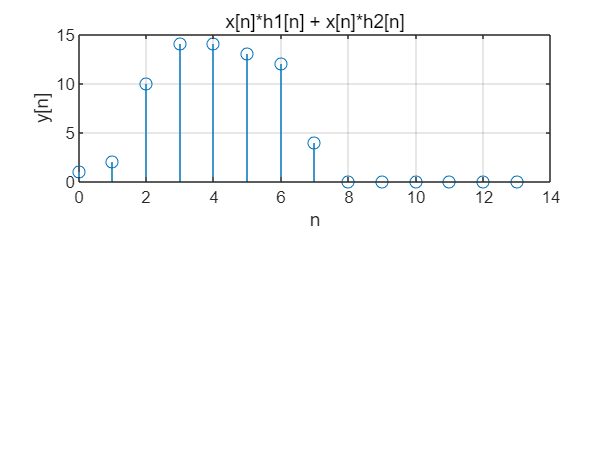

subplot(2, 1, 1);
stem(ny, y_plus);
title("x[n]*h1[n] + x[n]*h2[n]");
xlabel("n")
ylabel("y[n]");
grid on;

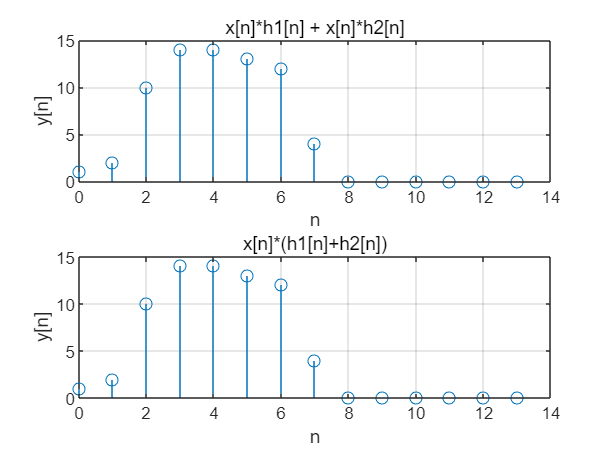

subplot(2, 1, 2);
stem(ny, y);
title("x[n]*(h1[n]+h2[n])");
xlabel("n")
ylabel("y[n]");
grid on;